# Estimation of elastic properties of H313_HTI sample

**Author**: Martin Rühlmann, Abakumov Ivan

**Publication date**: 24th October 2019

**E-mail**: abakumov_ivan@mail.ru

## Introduction

Some bla bla bla here))

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## 1. Upload the data

Sample = MLD('/remote/data/ivan/Ultrasonic_data/H313_HTI_ivan/Sample_H313_HTI_data.mat');
Sample.Theta = Sample.Theta+90; 
Sample.Theta(Sample.Theta>360) = Sample.Theta(Sample.Theta>360)-360;

%ind1 = [1:9 13:35];          % seria of measurements 
%ind2 = [38:48 54:72];            % another at 90 degree
ind1 = 18:35;          % seria of measurements 
ind2 = 56:72;            % another at 90 degree

## Plot velocities

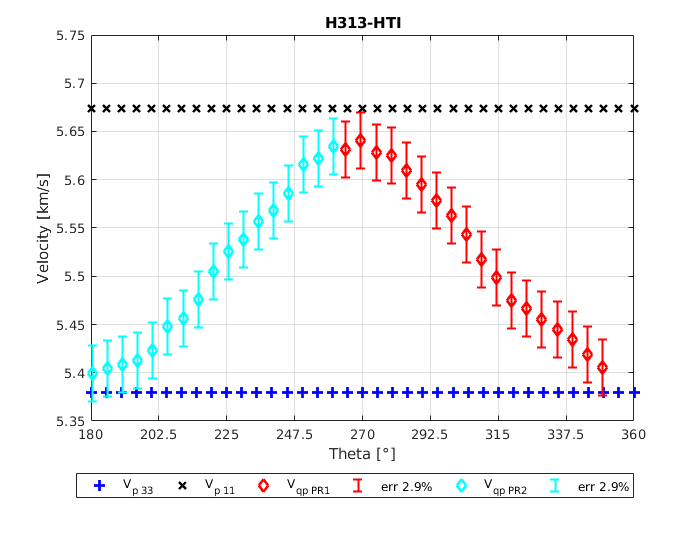

figure(1733)       % P velocities
fig = figure('Position', [1 1 700 550]);
plot (Sample.Theta, Sample.Vp33,'b+','MarkerSize', 7, 'LineWidth', 2)
hold on
plot (Sample.Theta, Sample.Vp11,'kx','MarkerSize', 7, 'LineWidth', 2)
plot (Sample.Theta(ind1)-0.5, Sample.Vqp(ind1),'rd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind1)));
errorbar(Sample.Theta(ind1)-0.5,Sample.Vqp(ind1),err,'r','LineStyle','none', 'LineWidth', 1.5);
plot (Sample.Theta(ind2)+0.5, Sample.Vqp(ind2),'cd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind2)));
errorbar(Sample.Theta(ind2)+0.5,Sample.Vqp(ind2),err,'c','LineStyle','none', 'LineWidth', 1.5);
xlabel('Theta [\circ]','LineWidth', 2)
ylabel('Velocity [km/s]', 'LineWidth', 2)
legend('V_{p 33}','V_{p 11}','V_{qp PR1}','err 2.9%','V_{qp PR2}','err 2.9%', 'Location', 'southoutside', 'Orientation','horizontal')
title('H313-HTI')
xticks(180:22.5:360)
xticklabels(180:22.5:360)
axis([180 360 5.35 5.75]);
grid on

## 2. Conventional analyses of Thomsen's parameters

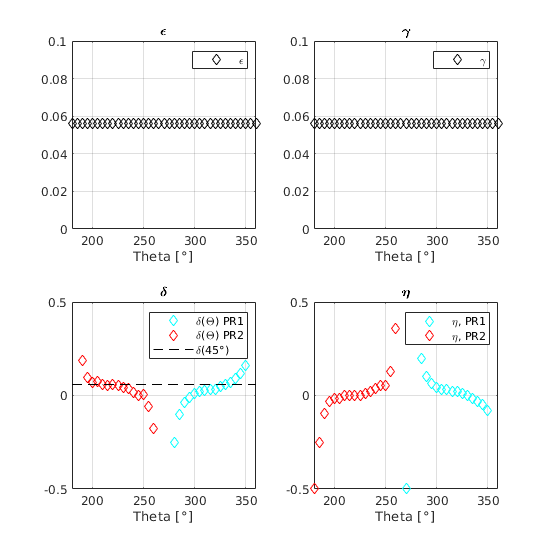

C11 = Sample.rho*Sample.Vp11.^2;
C33 = Sample.rho*Sample.Vp33.^2; 
C44 = Sample.rho*Sample.Vs31.^2; 
C66 = Sample.rho*Sample.Vs21.^2; 
Cqp = Sample.rho*Sample.Vqp.^2;
C12 = C11 - 2*C66;

ST2 = (sin(Sample.Theta/180*pi)).^2; 
CT2 = (cos(Sample.Theta/180*pi)).^2; 

A = (C11 + C44).*ST2 + (C33 + C44).*CT2; 
B = (C11 - C44).*ST2 - (C33 - C44).*CT2; 

C13 = sqrt(((2*Cqp-A).^2 - B.^2)./(4*ST2.*CT2)) - C44;

gamma   = (C66 - C44)./(2*C44);
epsilon = (C11 - C33)./(2*C33);
delta = ((C13+C44).^2 - (C33-C44).^2)./(2*C33.*(C33-C44));
eta = (epsilon-delta)./(1+2*delta);

ind = ((Sample.Theta == 45) + (Sample.Theta == 135) + (Sample.Theta == 225)+ (Sample.Theta == 315)) == 1;
delta45.mean = mean(delta(ind)); 
delta45.std = std(delta(ind)); 


figure(21);
fig = figure('Position', [1 1 550 550]);

subplot(2,2,1)
plot(Sample.Theta,epsilon,'kd'); 
xlabel('Theta [\circ]','LineWidth', 2)
axis([180 360 0 0.1]);
legend('\epsilon')
grid on
title('\epsilon')

subplot(2,2,2)
plot(Sample.Theta,gamma,'kd'); 
xlabel('Theta [\circ]','LineWidth', 2)
axis([180 360 0 0.1]);
legend('\gamma')
grid on
title('\gamma')

subplot(2,2,3)
plot(Sample.Theta(ind1),delta(ind1),'cd'); 
hold on
plot(Sample.Theta(ind2),delta(ind2),'rd'); 
plot(Sample.Theta,delta45.mean*ones(size(Sample.Theta)),'k--'); 
legend('\delta(\Theta) PR1', '\delta(\Theta) PR2', '\delta(45\circ)')
xlabel('Theta [\circ]','LineWidth', 2)
axis([180 360 -0.5 0.5]);
grid on
title('\delta')

subplot(2,2,4)
plot(Sample.Theta(ind1),eta(ind1),'cd'); 
hold on 
plot(Sample.Theta(ind2),eta(ind2),'rd'); 
xlabel('Theta [\circ]','LineWidth', 2)
legend('\eta, PR1','\eta, PR2')
axis([180 360 -0.5 0.5]);
grid on
title('\eta')

## 3. Least squares analysis of Thomsen's parameters

### Visualize the data

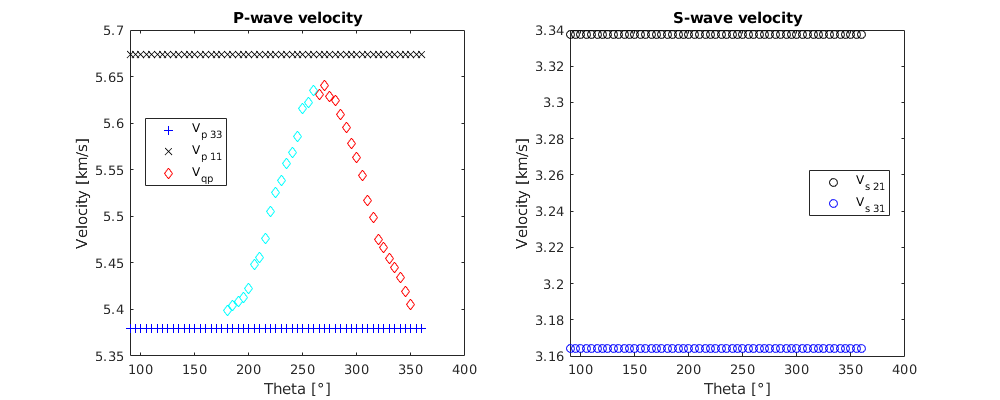

figure(122)
fig = figure('Position', [1 1 1000 400]);
subplot(1,2,1)
plot(Sample.Theta, Sample.Vp33, '+b');
hold on
plot(Sample.Theta, Sample.Vp11, 'xk');
plot(Sample.Theta(ind1), Sample.Vqp(ind1), 'dr');
plot(Sample.Theta(ind2), Sample.Vqp(ind2), 'dc');
xlabel('Theta [\circ]')
ylabel('Velocity [km/s]')
legend('V_{p 33}', 'V_{p 11}', 'V_{qp}','Location','best')
title('P-wave velocity')

subplot(1,2,2)
plot(Sample.Theta, Sample.Vs21, 'ko');
hold on 
plot(Sample.Theta, Sample.Vs31, 'bo');
xlabel('Theta [\circ]')
ylabel('Velocity [km/s]')
legend('V_{s 21}','V_{s 31}','Location','best')
title('S-wave velocity')

### Assign C values

Sample.C11 = C11;
Sample.C33 = C33;
Sample.C44 = C44;
Sample.C66 = C66;
Sample.Vqp = Sample.Vqp;

ind = [ind1 ind2];
iSample.Theta = Sample.Theta(ind);
iSample.Vp33 = Sample.Vp33(ind);
iSample.Vp11 = Sample.Vp11(ind);
iSample.Vs31 = Sample.Vs31(ind);
iSample.Vs21 = Sample.Vs21(ind);
iSample.Vqp = Sample.Vqp(ind);
iSample.C11 = Sample.C11(ind);
iSample.C33 = Sample.C33(ind);
iSample.C44 = Sample.C44(ind);
iSample.C66 = Sample.C66(ind);
iSample.rho = Sample.rho; 

### Find optimum delta

testdelta = -0.1:0.001:0.2;
dtheta = -10:0.1:10;
tic
nSample = iSample; 
JJ = zeros(length(dtheta),length(testdelta));
for i=1:length(dtheta)
    nSample.Theta = iSample.Theta + dtheta(i);
    J = costFunction_delta(nSample,testdelta);
    JJ(i,:) = J; 
end
toc

Elapsed time is 0.236809 seconds.



[~, minind] = min(JJ(:));
[inda, indd] = ind2sub(size(JJ),minind);
 
thetapl = dtheta(inda);
delta = testdelta(indd);

### Plot final results 

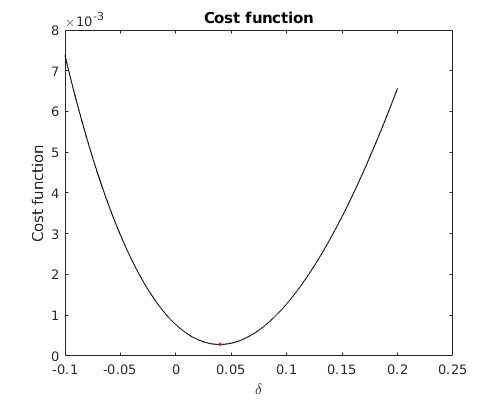

figure(343)
fig = figure('Position', [1 1 500 400]);
plot(testdelta, squeeze(JJ(inda,:)), 'k-');
hold on 
plot(testdelta(indd), JJ(inda,indd), 'r.','MarkerSize', 7);
xlabel('\delta')
ylabel('Cost function')
title('Cost function')

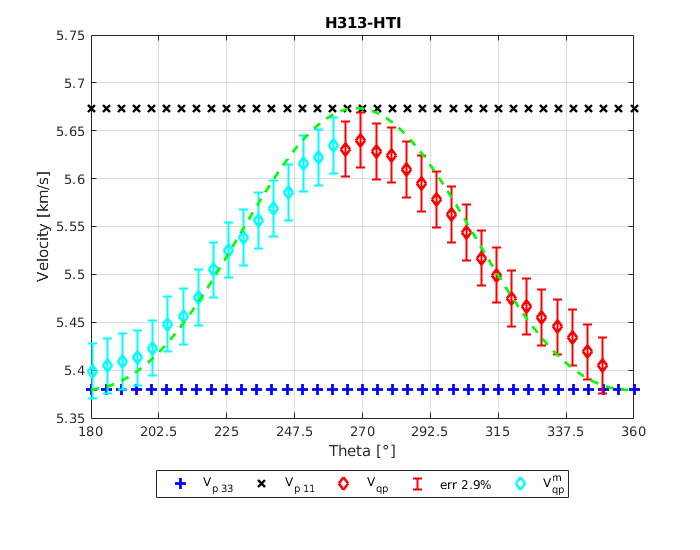


nSample.Theta = 0:1:360;
Vqp = get_Vqp_VTI(nSample,delta);

 
figure(147)
fig = figure('Position', [1 1 700 550]);
plot (Sample.Theta, Sample.Vp33,'b+','MarkerSize', 7, 'LineWidth', 2)
hold on
plot (Sample.Theta, Sample.Vp11,'kx','MarkerSize', 7, 'LineWidth', 2)
plot (Sample.Theta(ind1)-0.5, Sample.Vqp(ind1),'rd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind1)));
errorbar(Sample.Theta(ind1)-0.5,Sample.Vqp(ind1),err,'r','LineStyle','none', 'LineWidth', 1.5);
plot (Sample.Theta(ind2)+0.5, Sample.Vqp(ind2),'cd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind2)));
errorbar(Sample.Theta(ind2)+0.5,Sample.Vqp(ind2),err,'c','LineStyle','none', 'LineWidth', 1.5);
plot(nSample.Theta-thetapl, Vqp, 'g--', 'LineWidth', 2)
xlabel('Theta [\circ]','LineWidth', 2)
ylabel('Velocity [km/s]', 'LineWidth', 2)
legend('V_{p 33}','V_{p 11}','V_{qp}','err 2.9%','V_{qp}^m', 'Location', 'southoutside', 'Orientation','horizontal')
title('H313-HTI')
xticks(180:22.5:360)
xticklabels(180:22.5:360)
axis([180 360 5.35 5.75]);
grid on

## 3. Least squares analysis of Thomsen's parameters (weak anisotropy approximation)

Alpha   = linspace(5.35,5.45,101);
Delta   = linspace(-0.0,0.10,101);
Epsilon = linspace(0.02,0.12,101);
dTheta  = linspace(-5,5,26);

tic
J = costFunction_delta_weak(iSample,Alpha,Delta,Epsilon,dTheta);
toc

Elapsed time is 60.167498 seconds.



[~, ind] = min(J(:));
[inda,indd,inde,indt] = ind2sub(size(J),ind);
 
result.alpha = Alpha(inda);
result.delta = Delta(indd);
result.epsilon = Epsilon(inde);
result.dtheta = dTheta(indt);

## 3a. Alternative idea with L-BFGS-B method

save('/home/ivan/Desktop/MLIB/UMM/TempSample.mat','Sample');


x0  = [5.40 0.05 0.07   0];   % The starting point.
lb  = [5.35 0.0  0.02 -10];  % Lower bound on the variables.
ub  = [5.45 0.1  0.12 +10];  % Upper bound on the variables.

tic
x = lbfgsb(x0,lb,ub,'ComputeObjectiveSample','ComputeGradientSample',...
               [],'genericcallback','maxiter',80,'m',4,'factr',1e-12,...
               'pgtol',1e-5);

  1  0.000533 
  2  0.000469 
  3  0.000245 
  4  0.000244 
  5  0.000239 


toc

Elapsed time is 0.713724 seconds.



result.alpha = x(1);
result.delta = x(2);
result.epsilon = x(3);
result.dtheta = x(4);

## Plot the result:

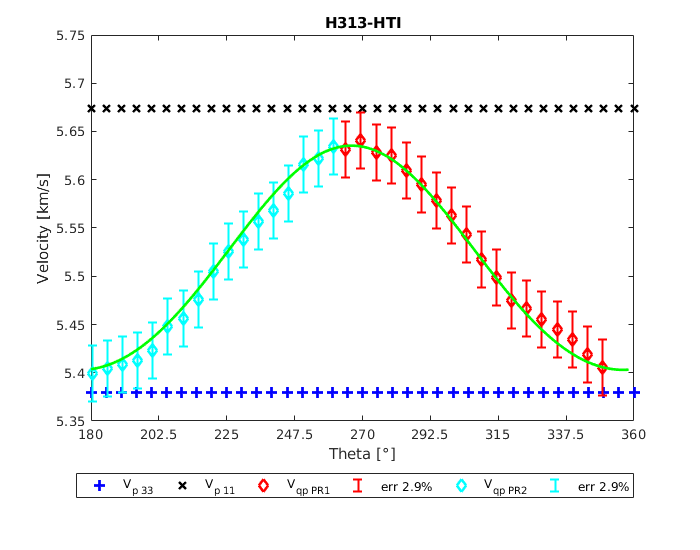

figure(27)
fig = figure('Position', [1 1 1200 800]);

nSample.Theta = 0:1:360;
Vqp = get_Vqp_VTI_weak(nSample,result.alpha,result.delta,result.epsilon,result.dtheta);

figure(144)
fig = figure('Position', [1 1 700 550]);
plot (Sample.Theta, Sample.Vp33,'b+','MarkerSize', 7, 'LineWidth', 2)
hold on
plot (Sample.Theta, Sample.Vp11,'kx','MarkerSize', 7, 'LineWidth', 2)
plot (Sample.Theta(ind1)-0.5, Sample.Vqp(ind1),'rd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind1)));
errorbar(Sample.Theta(ind1)-0.5,Sample.Vqp(ind1),err,'r','LineStyle','none', 'LineWidth', 1.5);
plot (Sample.Theta(ind2)+0.5, Sample.Vqp(ind2),'cd','MarkerSize', 7, 'LineWidth', 2)
err = 0.029*ones(size(Sample.Vqp(ind2)));
errorbar(Sample.Theta(ind2)+0.5,Sample.Vqp(ind2),err,'c','LineStyle','none', 'LineWidth', 1.5);
plot(nSample.Theta-result.dtheta, Vqp, 'g-', 'LineWidth', 2)
xlabel('Theta [\circ]','LineWidth', 2)
ylabel('Velocity [km/s]', 'LineWidth', 2)
legend('V_{p 33}','V_{p 11}','V_{qp PR1}','err 2.9%','V_{qp PR2}','err 2.9%', 'Location', 'southoutside', 'Orientation','horizontal')
title('H313-HTI')
xticks(180:22.5:360)
xticklabels(180:22.5:360)
axis([180 360 5.35 5.75]);

## 4. Find errors of estimated parameters

% angle error std: 3 grad  =>> error in velocity 25 m/s
% error in velocity due to measurements =>> 15 m/s
% total error: 30 m 
%                                     37 mrasurement 73
% variance for velocity error 30 m = 0.010;   0.0060
% variance for velocity error 100 m = 0.030   0.020

Alpha   = linspace(5.35,5.45,26);
Delta   = linspace(-0.0,0.10,26);
Epsilon = linspace(0.02,0.12,26);
dTheta  = linspace(-5,5,11);

x0  = [5.40 0.05 0.07   0];   % The starting point.
lb  = [5.35 0.0  0.02 -10];  % Lower bound on the variables.
ub  = [5.45 0.1  0.12 +10];  % Upper bound on the variables.

Theta = iSample.Theta;
iiSample = iSample; 

clear test; 

for i=1:1:100

    iiSample.Theta = Theta + 1*randn(size(Theta));
    Vqptrue = get_Vqp_VTI_weak(iiSample,result.alpha,result.delta,result.epsilon,result.dtheta);

    VqpE = Vqptrue.*(1+0.015*randn(size(Vqptrue)));
    iiSample.Vqp = VqpE; 
    iiSample.Theta = Theta; 

    %J = costFunction_delta_weak(iSample,Alpha,Delta,Epsilon,dTheta);

    %[~, ind] = min(J(:));
    %[inda,indd,inde,indt] = ind2sub(size(J),ind);
    
    

    %test.alpha(i) = Alpha(inda);
    %test.delta(i) = Delta(indd);
    %test.epsilon(i) = Epsilon(inde);
    %test.dtheta(i) = dTheta(indt);
    
    save('/home/ivan/Desktop/MLIB/UMM/TempSample.mat','iiSample');

    
    x = lbfgsb(x0,lb,ub,'ComputeObjectiveSample','ComputeGradientSample',...
               [],'genericcallback','maxiter',80,'m',4,'factr',1e-12,...
               'pgtol',1e-5);

    
    test.alpha(i) = x(1);
    test.delta(i) = x(2);
    test.epsilon(i) = x(3);
    test.dtheta(i) = x(4);

end

  1  0.00353 
  2  0.00348 
  3  0.0033 
  4  0.00329 
  5  0.00325 
  6  0.00325 
  7  0.00325 
  8  0.00325 
  9  0.00325 
 10  0.00325 
 11  0.00325 
 12  0.00325 
 13  0.00325 
 14  0.00325 
 15  0.00325 
 16  0.00325 
 17  0.00325 
 18  0.00325 
 19  0.00324 
 20  0.00324 
 21  0.00324 
 22  0.00322 
 23  0.00322 
 24  0.00321 
 25  0.00321 
 26  0.00321 
 27  0.00321 
 28  0.00321 
 29  0.00321 
 30  0.00321 
 31  0.00321 
 32  0.00321 
 33  0.00321 
  1  0.0036 
  2  0.0036 
  3  0.00359 
  4  0.00359 
  5  0.00359 
  6  0.00359 
  7  0.00359 
  8  0.00359 
  9  0.00359 
 10  0.00359 
 11  0.00359 
 12  0.00359 
 13  0.00359 
 14  0.00359 
 15  0.00359 
 16  0.00358 
 17  0.00358 
 18  0.00358 
 19  0.00358 
 20  0.00358 
 21  0.00358 
 22  0.00358 
  1  0.00292 
  2  0.00292 
  3  0.0029 
  4  0.00289 
  5  0.00288 
  6  0.00288 
  7  0.00288 
  8  0.00288 
  9  0.00288 
 10  0.00288 
 11  0.00288 
 12  0.00288 
 13  0.00288 
 14  0.00288 
 15  0.00288 
 16  0.00288 
 17  0.002

## Plot results:

figure(33)
subplot(2,2,1); 
histfit(test.alpha',21)
xlabel('V_{P0}, [m/s]')
dist = fitdist(test.alpha(1:100)','Normal');
disp(['ALPHA: Relative error: ' num2str(abs(result.alpha-dist.mu)/result.alpha*100) '%'])

ALPHA: Relative error: 0.016694%


alpha_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,4) ' \sigma=' num2str(dist.sigma,2)])

subplot(2,2,2); 
histfit(test.delta',11)
xlabel('\delta')
dist = fitdist(test.delta(1:100)','Normal');
disp(['DELTA: Relative error: ' num2str(abs(result.delta-dist.mu)/result.delta*100) '%'])

DELTA: Relative error: 6.1698%


delta_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,2) ' \sigma=' num2str(dist.sigma,2)])

subplot(2,2,3); 
histfit(test.epsilon',11)
xlabel('\epsilon')
dist = fitdist(test.epsilon(1:100)','Normal');
disp(['EPSILON: Relative error: ' num2str(abs(result.epsilon-dist.mu)/result.epsilon*100) '%'])

EPSILON: Relative error: 0.11007%


epsilon_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,2) ' \sigma=' num2str(dist.sigma,2)])
%
subplot(2,2,4); 
histfit(test.dtheta',5)
xlabel('\Delta\theta')
dist = fitdist(test.dtheta(1:100)','Normal');
disp(['DTHETA: Absolute error: ' num2str(result.dtheta-dist.mu)])

DTHETA: Absolute error: 0.044541


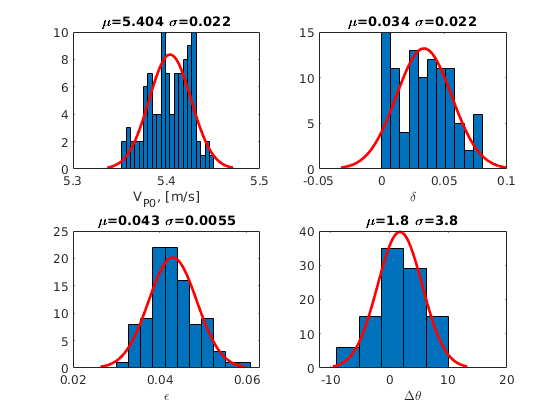

dtheta_err = 2*dist.sigma; 
title(['\mu=' num2str(dist.mu,2) ' \sigma=' num2str(dist.sigma,2)])